load  'pub_dataset3.mat'
tic

n = numel(data_tr(:,55));
rng(1) % For reproducibility
idx = randsample(n,n);
X = data_tr(idx,1:54);
Y = data_tr(idx,55);

initobs = 50;
Mdl = incrementalClassificationNaiveBayes('MaxNumClasses',2,'MetricsWindowSize',1000,...
    'Metrics','classiferror','MetricsWarmupPeriod',initobs);

Mdl = fit(Mdl,X(1:initobs,:),Y(1:initobs));

haveTrainedAllClasses = numel(unique(Y(1:initobs))) == 2

haveTrainedAllClasses = logical
   1


Preallocation

numObsPerChunk = 50;
nchunk = floor((n - initobs)/numObsPerChunk);
mu21 = zeros(nchunk,1);
ce = array2table(nan(nchunk,2),'VariableNames',["Cumulative" "Window"]);
trained = false(nchunk,1);

% Incremental fitting
for j = 1:nchunk
    ibegin = min(n,numObsPerChunk*(j-1) + 1 + initobs);
    iend   = min(n,numObsPerChunk*j + initobs);
    idx = ibegin:iend;
    Mdl = updateMetrics(Mdl,X(idx,:),Y(idx));
    ce{j,:} = Mdl.Metrics{"ClassificationError",:};
    if ce{j,"Window"} > 0.005
        Mdl = fit(Mdl,X(idx,:),Y(idx));
        trained(j) = true;
    end
    mu21(j) = Mdl.DistributionParameters{2,1}(1);
end

t = tiledlayout(2,1);
nexttile
plot(mu21)
hold on
plot(find(trained),mu21(trained),'r.')
ylabel('\mu_{21}')
legend('\mu_{21}','Training occurs','Location','best')

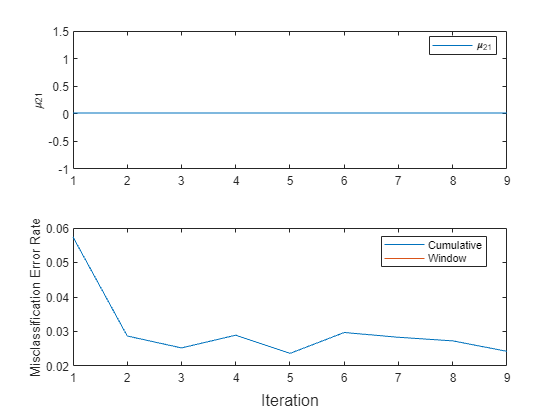

hold off
nexttile
plot(ce.Variables)
ylabel('Misclassification Error Rate')
legend(ce.Properties.VariableNames,'Location','best')
xlabel(t,'Iteration')

 Mdl = updateMetrics(Mdl,data_tr(:, 1:54),data_tr(:,55));
    ce = Mdl.Metrics{"ClassificationError",:}

ce =     0.0247       NaN


output_test = predict(Mdl,data_tr(:, 1:54));
accuracy = sum(output_test == data_tr(:,55))/numel(data_tr(:,55))

accuracy = 0.9760

precision = sum(output_test & data_tr(:,55)) / sum(output_test)

precision = 0.9745

recall = sum(output_test & data_tr(:,55)) / sum(data_tr(:,55))

recall = 0.9745

F1_score = 2 * (precision * recall) / (precision + recall)

F1_score = 0.9745

waktu = toc

waktu = 0.6760